# **利用 ode45 等绘制电力线**

**        求解常微分方程数值解常用ode函数，该系列函数包括ode23，ode45，ode15s等。常见经典形式为 [T Y]=ode15s(odefun;tspan;y0)，其中等号左侧为：T——离散时间点序列，Y——未知函数在T所对应时刻的函数值。等号右侧为：odefun——未知函数句柄，tspan——参数t变化的区间，y0——当t为0时各个待求函数的函数值。**

**       了解电力线的方程，并且熟悉了在 MATLAB下ode45 函数的应用之后，就可以利用力线方程绘制电力线。需要指出的是，利用 ode45 函数求解一次，只可以绘制一条电力线，其初始位置为[x(0),y(0),z(0)]，由求解方程组的初始条件确定。因此，要绘制一幅比较完美的电力线分布图，需要多次调用 ode45 函数，并且赋予不同的初始位置。为了选择初始位置,围绕两个点电荷，各选择一个小圆，然后将圆周均分为若干份，选择圆周上的点作为初始点。**

- **电场分布计算：**

**        以两点电荷系统为例，场点***** P*****(*****x*****,*****y*****)的电势（如果仅仅为了绘制电力线，可以不考虑系数**$q_1 /4\pi \varepsilon$**）可表示为：**


$$\phi =\frac{1}{\sqrt{(x+a)^2 +y^2 }}+\frac{Q^* }{\sqrt{(x-a)^2 +y^2 }}$$


**其中，两个点电荷分别位于**$(-a,0)$**，**$(a,0)$**，**$$$Q ^ { * } = q _ { 2 } / q _ { 1 }$$$**，则由**$$$E = - \nabla \phi$$$**得到的场强E在xoy平面只有两个分量：**


$$$$E _ { x } = - \frac { \partial \phi } { \partial x } , \quad E _ { y } = - \frac { \partial \phi } { \partial y }$$$$


**代入两式可得：**


$$$$\left\{ \begin{array} { l } { E _ { x } = \frac { x + a } { [ ( x + a ) ^ { 2 } + y ^ { 2 } ] ^ { 3 / 2 } } + Q ^ { * } \frac { x - a } { [ ( x - a ) ^ { 2 } + y ^ { 2 } ] ^ { 3 / 2 } } } \\ { E _ { y } = \frac { y } { [ ( x + a ) ^ { 2 } + y ^ { 2 } ] ^ { 3 / 2 } } + Q ^ { * } \frac { y } { [ ( x - a ) ^ { 2 } + y ^ { 2 } ] ^ { 3 / 2 } } } \end{array} \right.$$$$


- **利用ode函数求解同性电荷电力线分布：**

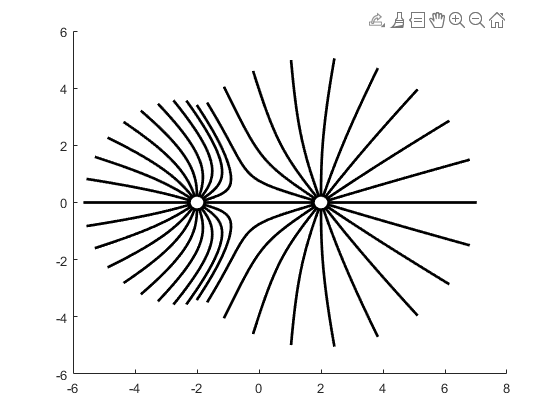

clc
clear
a= 2 ;      %电荷分别位于（a，0）和（-a，0）两点
Q=4;     %Q代表连个电荷的比值
r=0.1*a;                         %起始点所在圆半径
k=20;                            %电力线条数
theta=linspace(0,2*pi-2*pi/k,k); %起始点所对应是圆周上的角度分布
y1=r*sin(theta);
x1=-a+r*cos(theta);
x2=a+r*cos(theta);
x0=[x1 x2];
y0=[y1 y1];
figure;
hold on;                         %叠加绘图模式，画出所有电力线
for i=1:2*k                      %分别绘制每一条电力线
    [t,Z]=ode15s(@(t,y) dcxfun(t,y,Q,a),[0 10],[x0(i),y0(i)]);     
    plot(Z(:,1),Z(:,2),'k','LineWidth',2);
end 
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **利用ode函数求解异性等量电荷电力线分布：**

**         当绘制等量异号电荷时，对于右边电荷发出的电力线，数值求解会出现非常慢的情况，且程序给出警告性错误。此时，可以利用对称性绘制右侧的电力线。**

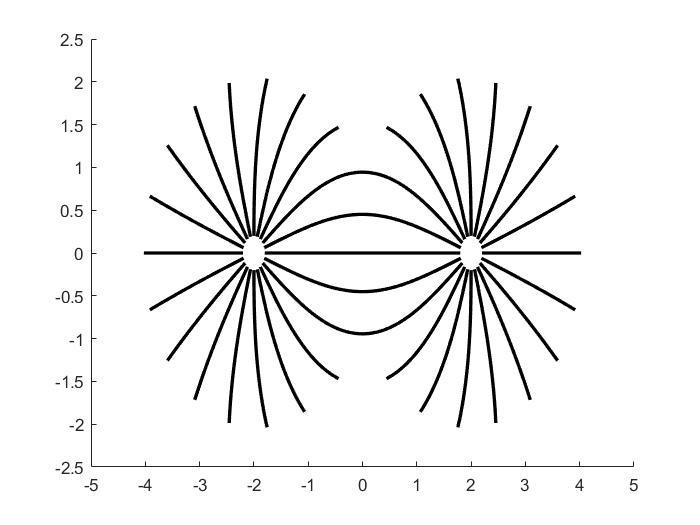

clc
clear            
figure;
a= 2;                             %电荷分别位于（a，0）和（-a，0）两点
r=0.1*a;                         %起始点所在圆半径
k=20;                            %电力线条数
theta=linspace(0,2*pi-2*pi/k,k); %起始点所对应是圆周上的角度分布
y2=r*sin(theta);
x2=-a+r*cos(theta);
x3=a+r*cos(theta);
x4=[x2 x3];
y4=[y2 y2];
hold on;                         %叠加绘图模式，画出所有电力线
for i=1:k                       %分别绘制每一条电力线
    [t,Y]=ode15s(@dcxfun2,[0 3],[x4(i),y4(i)]);     
    plot(Y(:,1),Y(:,2),'k','Linewidth',2);
    plot(-Y(:,1),Y(:,2),'k','linewidth',2);
end
set(gcf,'Visible','on');   	    %强制图片弹出显示

function dy=dcxfun(t,y,Q,a)
    dy=[(y(1)+a)./(sqrt((y(1)+a).^2+y(2).^2).^3)+Q*(y(1)-a)./(sqrt((y(1)-a).^2+...
        y(2).^2).^3);y(2)./(sqrt((y(1)+a).^2+y(2).^2).^3)+Q*y(2)./(sqrt((y(1)-a).^2+y(2).^2).^3)];
end
function dy=dcxfun2(t,y)
    a=2;                    %电荷的位置
    dy=[(y(1)+a)./(sqrt((y(1)+a).^2+y(2).^2).^3)-(y(1)-a)./(sqrt((y(1)-a).^2+...
        y(2).^2).^3);y(2)./(sqrt((y(1)+a).^2+y(2).^2).^3)-y(2)./(sqrt((y(1)-a).^2+y(2).^2).^3)];
end